# Question 1

clear all;
clc;

uk = [-10, -5, 0, 5, 10]';
yk = [-18.9312, -8.2831, -0.3294, 11.2311, 20.9594]';
n = length(uk);

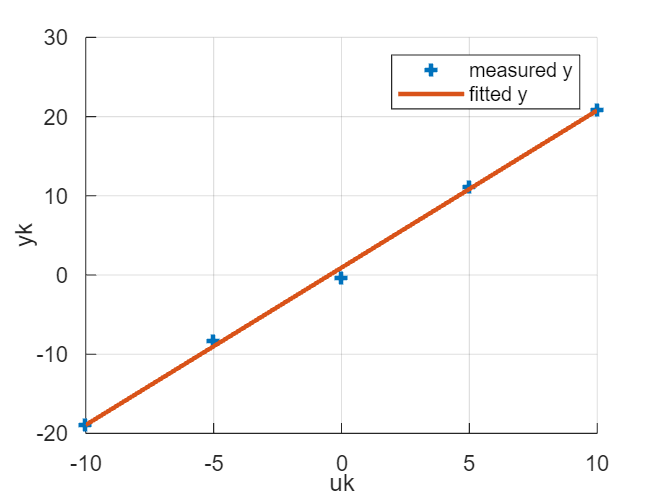

%Hardcode
figure
scatter(uk, yk, LineWidth=2,Marker="+")
grid on
xlabel('uk')
ylabel('yk')
hold on
Phi = [uk, ones(n,1)];
thetahat = Phi\yk;
y_pred = Phi*thetahat;
plot(uk, y_pred, LineWidth=2)
hold off
legend('measured y', 'fitted y')

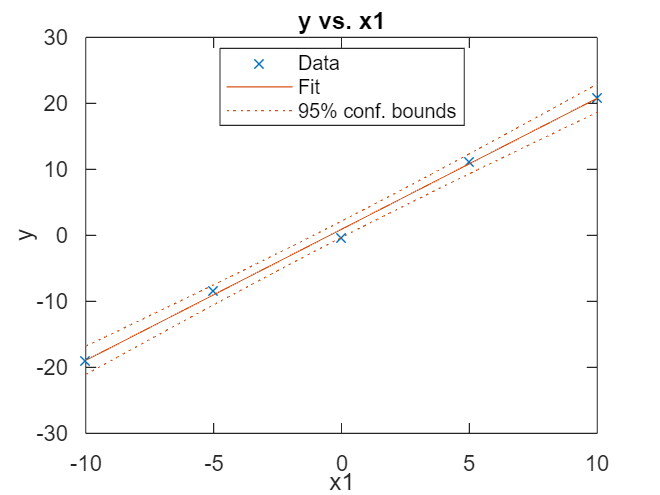

model = fitlm(uk,yk);
figure
grid on
plot(model)

## Question 2

data1 = load("datafileEx2.mat");

y = (data1.y)';
u = (data1.u)';
t = (data1.t)';
n = length(u)

n = 100

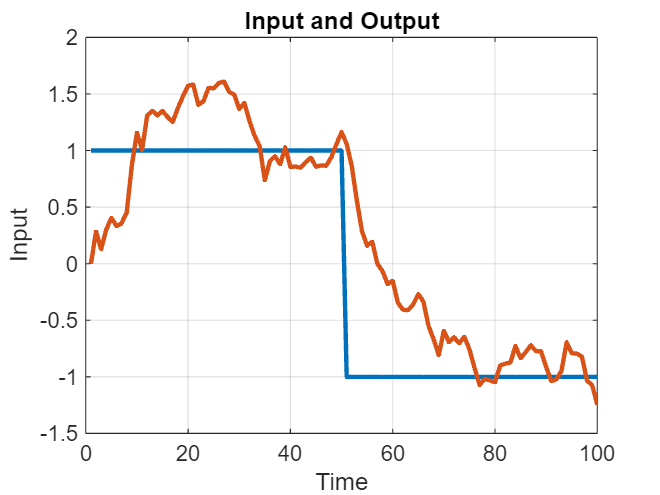

figure
plot(t, u, LineWidth=2)
grid on
xlabel('Time')
ylabel('Input')
hold on
plot(t, y, LineWidth=2)
xlabel('Time')
ylabel('Input')
title('Input and Output')
hold off

Phai = [-y(1:end-1), u(1:end-1)];
theta_hat = Phai\y(2:end);
a1 = theta_hat(1);
b1 = theta_hat(2);
y_hat = Phai*theta_hat;


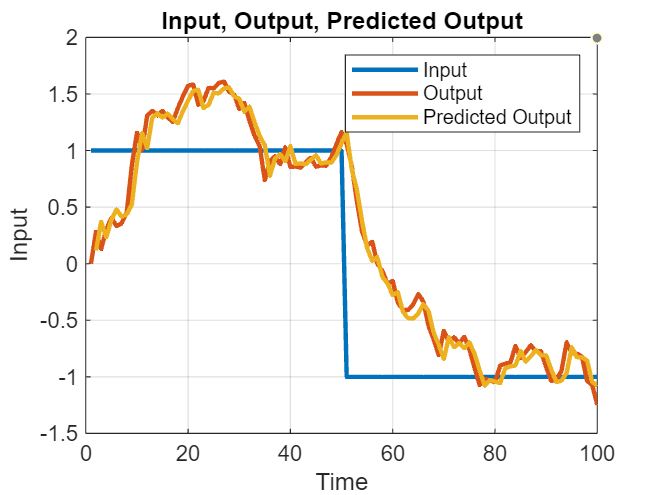

figure
plot(t, u, LineWidth=2)
grid on
xlabel('Time')
ylabel('Input')
hold on
plot(t, y, LineWidth=2)
xlabel('Time')
ylabel('Input')
plot(t(2:end), y_hat, LineWidth=2)
title('Input, Output, Predicted Output')
legend('Input', 'Output', 'Predicted Output')
hold off

N = length(u);
ysim = zeros(N,1);
for k = 2:N
    ysim(k) = [-ysim(k-1), u(k-1)] * theta_hat;
end

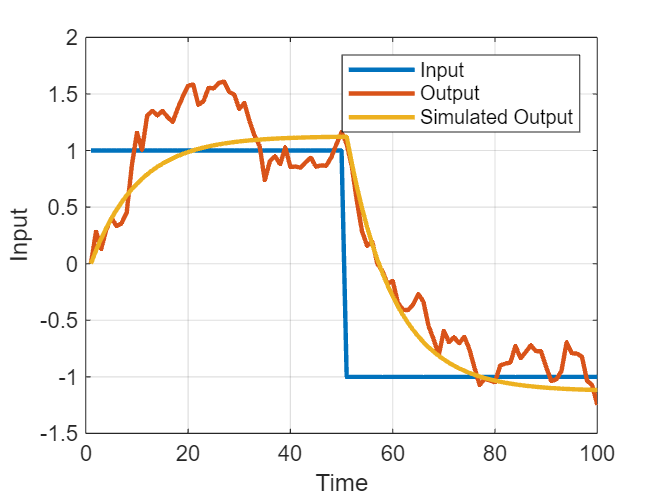

figure
plot(t, u, LineWidth=2)
grid on
xlabel('Time')
ylabel('Input')
hold on
plot(t, y, LineWidth=2)
xlabel('Time')
ylabel('Input')
plot(t, ysim, LineWidth=2)
legend('Input', 'Output', 'Simulated Output')
hold off

## Computing R-Squared

epsilon = y(2:end) - y_hat;

R2pred = 100*(1-var(epsilon)/var(y))

R2pred = 98.4546

SSR = sum((y(2:end)-y_hat).^2);
TSS = sum((y-mean(y)).^2);
R2pred2 = 100 * (1-SSR/TSS)

R2pred2 = 98.4516

R2Pred3 = 100 * (1 - (norm(y(2:end)-y_hat)^2/norm(y-mean(y))^2))

R2Pred3 = 98.4516

MSE = sum((y(2:end)-y_hat).^2)/N

MSE = 0.0133

IAE = sum(abs(y(2:end)-y_hat))/N

IAE = 0.0902

## System Identification

Created preference file "C:\Users\hp\Documents\MATLAB\idprefs.mat.".
Type HELP MIDPREFS if you want to move this file.


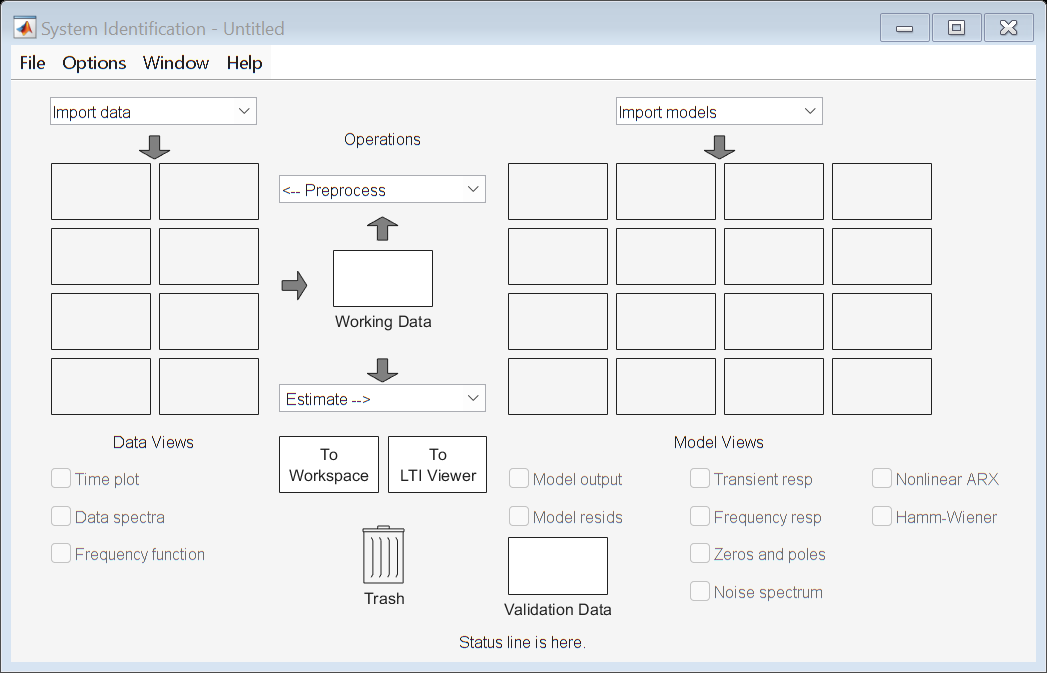

systemIdentification